#  Levenberg-Marquardt-Verfahren

Wir betrachten das nichtlineare Ausgleichsproblem aus Bespiel 6.1 (Buch):

           
$$\min_{x \in \mathbb{R}^4} \|F(x)\|_2,
$$


          
$$F_i(x):= x_1 e^{-x_2t_i} \sin(x_3 t_i +x_4) -b_i, ~~i=1,\ldots, 10,$$


mit den Werten $(t_i,b_i)$ aus Tabelle 6.1 (Buch).

Die Daten:

t=[0.1 0.3 0.7 1.2 1.6 2.2 2.7 3.1 3.5 3.9]';
b=[0.558 0.569 0.176 -0.207 -0.133 0.132 0.055 -0.090 -0.069 0.027]';

Startwerte für das  Levenberg-Marquardt-Verfahren:

xold=[1, 2, 2, 4]';
mu=0.1

mu = 0.1000

$\mu >0$: das  Levenberg-Marquardt-Verfahren wird verwendet (Default Startwert: $\mu=0.1$)

$\mu=0$: das Gauß-Newton-Verfahren wird verwendet.

In jedem Iterationsschritt des Verfahrens werden folgende Größen angezeigt:

- mu $=\mu$-Wert

- NormF$=\|F(x^k)\|_2$

- err$=\|\nabla \phi(x^k)\|_2$   (siehe Buch)

- KonvFaktor $=\|\nabla \phi(x^k)\|_2/\|\nabla \phi (x^{k-1})\|_2$

Als Stoppkriterium wird verwendet:  err $\leq 10^{-6}$ oder $k  \geq k_{\max}=30$.

Falls mit höchstens 30 Iterationen die vorgebene Toleranz erreicht wird, werden $k$ (Anzahl der Iterationen) und $x^k$ (berechnete optimale Parameterwerte) gezeigt.

Beachte, dass $F(x_1,x_2,x_3,x_4)=F(-x_1,x_2,x_3,x_4\pm \pi)$gilt, und deshalb mehrere lokale Minima mit gleichem Residuum existieren.

# Aktivität:

Sie können den Startwert ändern und die Resultate des Levenberg-Marquardt-Verfahrens ($\mu >0$) mit den Resultaten des Gauß-Newton-Verfahrens ($\mu=0$) vergleichen.

## Levenberg-Marquardt-Verfahren  (mu=0: Gauss-Newton)

k=0; kmax=30; epsilon=10^(-6);
%% mu:=0: das Gauss-Newton-Verfahren wird verwendet
err=1;
Fvalue=F(xold,t,b);
A=DF(xold,t,b);
errold=norm(A'*Fvalue);
Erg= zeros(2,kmax+1);
Erg(:,1)= [errold; norm(Fvalue)];

while ((k < kmax) && (err >epsilon))
    rhs=[Fvalue; zeros(4,1)];
    Amu=[A; mu*eye(4,4)];
    s=Amu\(-rhs); %lineares Ausgleichsproblem wird gelöst
    accept=false;
    if (mu==0)   % Das Gauss-Newton-Verfahren
        accept=true;  
    end
    while (accept==false)
        [accept,munew]=test(xold,Fvalue,A,s,mu,t,b);  % mu-Wert wird ggf. angepasst
        if accept==false
            mu=munew;
            Amu=[A; mu*eye(4,4)];
            s=Amu\(-rhs); % lineares Ausgleichsproblem wird gelöst
        else 
            mu=munew
        end
    end 
    xnew=xold+s;
    Fvalue=F(xnew,t,b);
    fprintf('\nIteration %u: \n',k+1);
    NormF=norm(Fvalue)
    A=DF(xnew,t,b);
    err=norm(A'*Fvalue)
    KonvFactor=err/errold
    disp('----------------');  
    errold=err;
    xold=xnew;
    k=k+1;
    Erg(:,k+1)= [err; NormF];
end

mu = 0.0500


Iteration 1: 


NormF = 0.4724

err = 0.2266

KonvFactor = 0.1321

----------------


mu = 0.0250


Iteration 2: 


NormF = 0.2933

err = 0.0707

KonvFactor = 0.3119

----------------


mu = 0.0250


Iteration 3: 


NormF = 0.1611

err = 0.1105

KonvFactor = 1.5628

----------------


mu = 0.0125


Iteration 4: 


NormF = 0.0894

err = 0.0094

KonvFactor = 0.0847

----------------


mu = 0.0063


Iteration 5: 


NormF = 0.0890

err = 1.7809e-04

KonvFactor = 0.0190

----------------


mu = 0.0063


Iteration 6: 


NormF = 0.0890

err = 6.1192e-05

KonvFactor = 0.3436

----------------


mu = 0.0063


Iteration 7: 


NormF = 0.0890

err = 1.9779e-05

KonvFactor = 0.3232

----------------


mu = 0.0063


Iteration 8: 


NormF = 0.0890

err = 6.9764e-06

KonvFactor = 0.3527

----------------


mu = 0.0063


Iteration 9: 


NormF = 0.0890

err = 2.3857e-06

KonvFactor = 0.3420

----------------


mu = 0.0063


Iteration 10: 


NormF = 0.0890

err = 8.3415e-07

KonvFactor = 0.3496

----------------


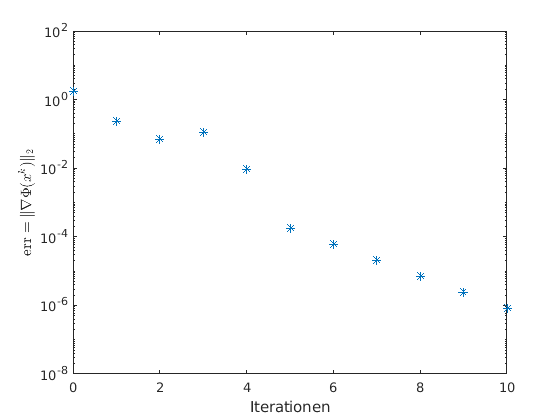

visualizeIter(Erg,k);


Toleranz erreicht nach k = 10 Iterationen 



Optimale Parameterwerte: 


result =    -0.7354
    0.7962
    3.0745
    3.7458


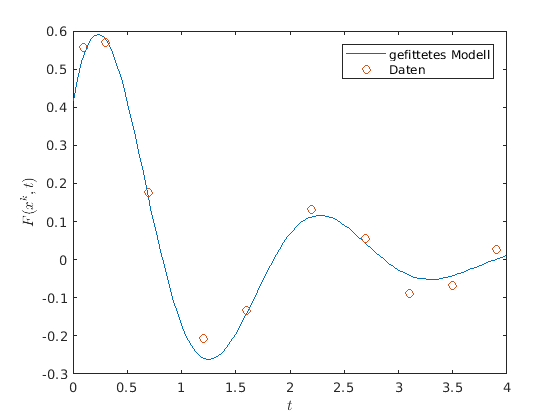


if (err > epsilon)
    fprintf('\nToleranz nicht erreicht in 30 Iterationen \n');
else
    fprintf('\nToleranz erreicht nach k = %u Iterationen \n',k);
    fprintf('\nOptimale Parameterwerte: \n');
    result=xnew
    visualizeSol(xnew,t,b)
end

In der Funktion `test` wird geprüft, ob die aktuelle Korrektur $s$ akzeptiert wird und der $\mu$-Wert angepasst (siehe Buch für Erklärung der Methode).

function [accept,munew]=test(xold,Fold,DFold,s,mu,t,b)
    Fnew=F(xold+s,t,b);
    r1=0.5*(Fold'*Fold-Fnew'*Fnew);
    r2=-0.5*s'*DFold'*Fold;
    rhomu=r1/r2;
    if (rhomu <=0)
        accept=false;
        munew=2*mu;
    else
        accept=true;
        if (rhomu <0.25)
            munew=2*mu;
        elseif (rhomu>0.75)
            munew=0.5*mu;
        else
            munew=mu;
        end
    end
end
    

In der Funktion `DF` wird die Jacobi-Matrix bestimmt.

function [DFout]=DF(x,t,b)
    DFout=zeros(10,4);
    for i=1:10
        DFout(i,1)= exp(-x(2)*t(i))*sin(x(3)*t(i)+x(4));
        DFout(i,2)= -x(1)*t(i)*exp(-x(2)*t(i))*sin(x(3)*t(i)+x(4));
        DFout(i,3)= x(1)*t(i)*exp(-x(2)*t(i))*cos(x(3)*t(i)+x(4));
        DFout(i,4)= x(1)*exp(-x(2)*t(i))*cos(x(3)*t(i)+x(4));
    end
end

In der Funktion `F` wird die Funktion $F$ ausgewertet. 

function [Fout]=F(x,t,b)
    Fout=zeros(10,1);
    for i=1:10
       Fout(i)=x(1)*exp(-x(2)*t(i))*sin(x(3)*t(i)+x(4))-b(i);
    end
end

Die Funktion `visualizeIter` plottet die Werte von err über die Iterationen $k$.

function visualizeIter(Erg,iter)
    semilogy(0:iter,Erg(1,1:iter+1),'*');
    xlabel('Iterationen');  ylabel('${\rm err}=\|\nabla \Phi(x^k)\|_2$','Interpreter','latex')
end

Die Funktion `visualizeSol` plottet das gefittete Modell $F(x^k)$ als Funktion vonn $t$ und die zugehörigen Daten $(t_i,b_i)$.

function visualizeSol(x,ti,bi)
    t=linspace(0,4);
    plot(t,x(1)*exp(-x(2).*t).*sin(x(3).*t+x(4)),ti,bi,'o');
    xlabel('$t$','Interpreter','latex');  ylabel('$F(x^k,t)$','Interpreter','latex')
    legend('gefittetes Modell','Daten')
end
